This file develops a fuzzy logic controller that utilizes two inputs (psi and psi dot), each of which have seven membership functions. Seven singleton outputs exist for the fuzzy rule base. Sampling time on hardware could only support 10ms, hence the c2d with 10ms.

clear;

%system dynamics

m_pend = 0.5;       %kg
m_cart = 0.2;       %kg
I_pend = 0.1;       %kg*m^2
l = 0.03;           %from rotation point to COM
g = 9.8;            %m/s^2
f = 0.01;           %frictional coefficient
K_T = 0.11;         %N*m/A
R_motor = 10;       %ohm
r_wheel = 0.0335;   %m

% SS matrices

A22 = -(I_pend+m_pend*l^2)*f / (I_pend*(m_cart + m_pend)+m_cart*m_pend*l^2);
A23 = (m_pend^2*g*l^2) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
A42 = (-m_pend*l*f) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
A43 = (m_pend*g*l*(m_cart+m_pend)) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);

A = [ 0 1 0 0;
    0 A22 A23 0;
    0 0 0 1;
    0 A42 A43 0];

B2 = (I_pend+m_pend*l^2)/(I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
B4 = (m_pend*l) / (I_pend*(m_cart+m_pend)+(m_cart*m_pend*l^2));

B = [0;
    B2;
    0
    B4];

C = [1 0 0 0;
    0 0 1 0];

D = [0;
    0];

[b,a] = ss2tf(A,B,C,D); %implicit ZoH

%create SS and TF model

ts = 0.01; %s -- limitation of hardware computation rate!

sys_cont = ss(A,B,C,D);
sys_disc = c2d(sys_cont, ts);
A = sys_disc.A; B = sys_disc.B; C = sys_disc.C; D = sys_disc.D;

NB: Negative Big, NM: Negative Medium, NS: Negative Small

Z: Zero

PB: Positive Big, PM: Positive Medium, PS: Positive Small

%input
NB_in = -20;
NM_in = -12;
NS_in = -3; 
Z_in = 0;
PS_in = 3; 
PM_in = 12; 
PB_in = 20; 

%output
NB = -255; 
NM = -150; 
NS = -40; 
Z = 0;
PS = 40; 
PM = 150; 
PB = 255; 


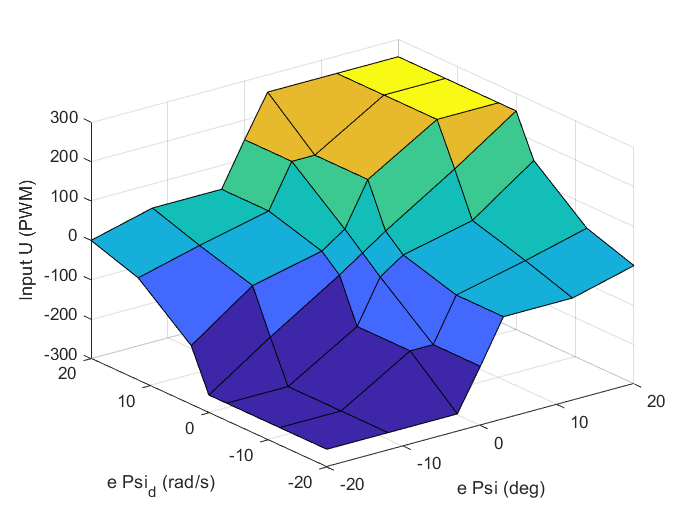

%only using error in psi and psi_d, not x_d error...

states = [NB_in,NM_in,NS_in,Z_in,PS_in,PM_in,PB_in];
[e_psi, e_psi_d] = meshgrid(states, states);
control_rule = [NB NB NB NM NS NS Z;
    NB NB NM NM NS Z PS;
    NB NB NM NS Z PS PM;
    NB NM NS Z PS PM PB;
    NM NS Z PS PM PB PB;
    NS Z PS PM PM PB PB;
    Z PS PS PM PB PB PB];
surf(e_psi, e_psi_d, control_rule)
xlabel('e Psi (deg)')
ylabel('e Psi_d (rad/s)')
zlabel('Input U (PWM)')

%Fuzzification constants

%CONSTANTS FOR PSI ERROR
c_NB_psi = -20; a_NB_psi = -.1;   %sigmoid
c_NM_psi = -12; sd_NM_psi= 3;  %gaussian
c_NS_psi= -3; sd_NS_psi = 2;  %gaussian
c_Z_psi = 0; sd_Z_psi = 1;   %gaussian
c_PS_psi = 3; sd_PS_psi = 2;   %gaussian
c_PM_psi = 12; sd_PM_psi = 3;  %gaussian
c_PB_psi = 20; a_PB_psi = .1;    %sigmoid

%CONSTANTS FOR PSI DOT ERROR
c_NB_psid = -2; a_NB_psid = -1;   %sigmoid
c_NM_psid = -.75; sd_NM_psid = .25;  %gaussian
c_NS_psid = -.25; sd_NS_psid = .25;  %gaussian
c_Z_psid = 0; sd_Z_psid = .25;   %gaussian
c_PS_psid = .25; sd_PS_psid = .25;   %gaussian
c_PM_psid = .75; sd_PM_psid = .25;  %gaussian
c_PB_psid = 2; a_PB_psid = 1;    %sigmoid

T = 3000;
time_step = 0.01;
time = linspace(1,T*time_step, T);
%zero reference for impulse response
ref = [zeros(1,length(time)); zeros(1,length(time)); zeros(1,length(time)); zeros(1,length(time))];

%constriants
Vmax = 7;
Vmin = -7;

%initial conditions
X = [0;0;0;0];
PWMact = 0.0;
UAct = 0.0; 

tic
for i = 1:(T)%T-1
    XAct(i,:) = X;
    
    %get errors
    err = ref - X;
    
    %convert error to degrees...
    err(3) = err(3)*180/pi;
    
    %input curve evaluation...
    
    %psi error
    u_NB_psi = sigmoid(err(3),c_NB_psi,a_NB_psi); 
    u_NM_psi = gaussian(err(3),c_NM_psi,sd_NM_psi);
    u_NS_psi = gaussian(err(3),c_NS_psi,sd_NS_psi); 
    u_Z_psi = gaussian(err(3),c_Z_psi,sd_Z_psi); 
    u_PS_psi = gaussian(err(3),c_PS_psi,sd_PS_psi); 
    u_PM_psi = gaussian(err(3),c_PM_psi,sd_PM_psi);
    u_PB_psi = sigmoid(err(3),c_PB_psi,a_PB_psi); 
    
    %array of psi errors
    u_psi = [u_NB_psi, u_NM_psi, u_NS_psi, u_Z_psi, u_PS_psi, u_PM_psi, u_PB_psi];

    %psi dot error
    u_NB_psid = sigmoid(err(4),c_NB_psid,a_NB_psid); 
    u_NM_psid = gaussian(err(4),c_NM_psid,sd_NM_psid); 
    u_NS_psid = gaussian(err(4),c_NS_psid,sd_NS_psid); 
    u_Z_psid = gaussian(err(4),c_Z_psid,sd_Z_psid); 
    u_PS_psid = gaussian(err(4),c_PS_psid,sd_PS_psid); 
    u_PM_psid = gaussian(err(4),c_PM_psid,sd_PM_psid);
    u_PB_psid = sigmoid(err(4),c_PB_psid,a_PB_psid); 
    
    %array of psi dot errors
    u_psid = [u_NB_psid, u_NM_psid, u_NS_psid, u_Z_psid, u_PS_psid, u_PM_psid, u_PB_psid];
    
    %create matrix to store rule evaluation
    ruleEvals = zeros(numel(u_psi), numel(u_psid));
    
    %rule avaluation from current states
    for ii = 1:numel(u_psi)
        for j = 1:numel(u_psid)
            ruleEvals(j,ii) = u_psi(ii) * u_psid(j);
        end
    end 
        
    %defuzzification
    weightedSum = sum((ruleEvals .* control_rule), 'all');
    defuzzOutput = weightedSum / sum(ruleEvals,'all');
    
    %fuzzy logic search to get PWM -> V -> U
    voltage = defuzzOutput / 255 * Vmax;
    %check for voltage saturation -- shouldn't exist because using fuzzy
    %logic pwm rules that account for saturation. But play it safe.
    voltage = min(Vmax,max(Vmin, voltage));
    %convert voltage to force, U
    U = 2 * K_T / (R_motor * r_wheel) * voltage;
    
    %update states
    X = A*X + B*U;
    
    %add impulses at certain step - modeled only as angular velocity
    %component
    if i == 400 
        X = X + [0;0;0;.4];
    end
        
    %store for graphing
    PWMact = [PWMact defuzzOutput];
    UAct = [UAct U]; 

end
toc

Elapsed time is 0.137223 seconds.


Plot Performance

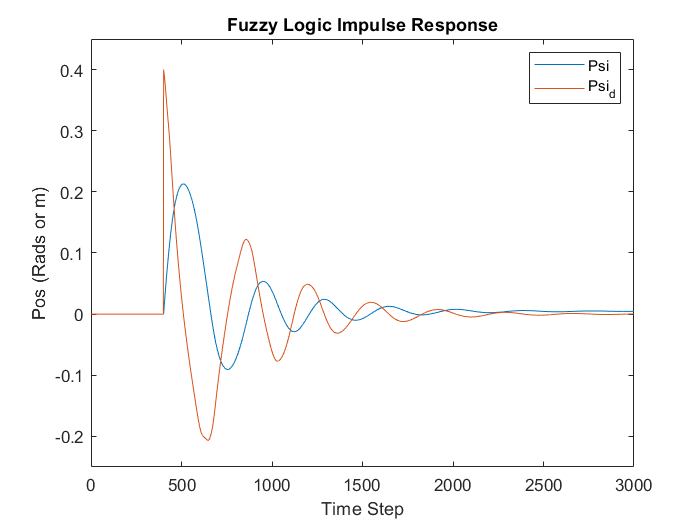

figure(1)
plot([1:T],XAct(:,3),[1:T],XAct(:,4)) 
ylim([-.25,.45]);
xlabel("Time Step");
ylabel("Pos (Rads or m)");
title("Fuzzy Logic Impulse Response")
legend("Psi", "Psi_d")

Plot Input Force

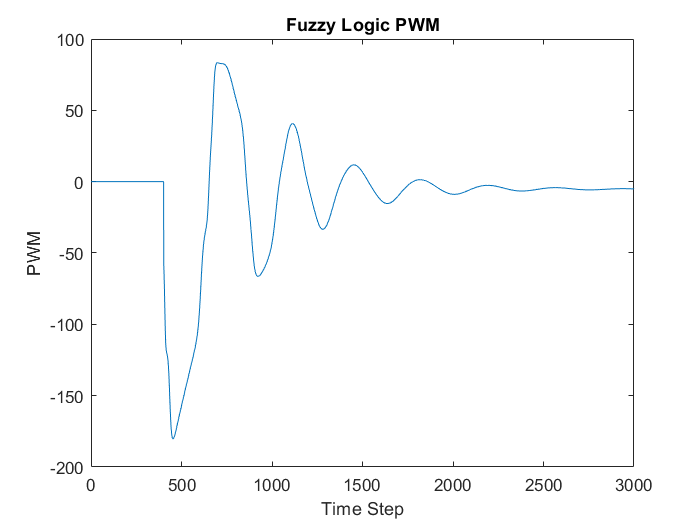

x = linspace(1, T+1, T+1);

figure(2)
plot(x, PWMact)
%ylim([-3,9]);
xlim([0,3000]);
xlabel("Time Step");
ylabel("PWM");
title("Fuzzy Logic PWM")

DEFINE FUNCTIONS

function f = sigmoid(x, c, a)
    f = 1 / (1 + (exp(-a*(x-c))));
end

function f = gaussian(x, c, sd)
    f = exp((-1/2)*((x-c)/sd)^2);
end